Draw a ROI and press Enter


Distance: 82.57 pixels


table_final = 42×2 table
      Var1      Amplitude 
    ________    __________

           0    4.2591e-12
    0.012431       0.40511
    0.024862       0.32399
    0.037292       0.23176
    0.049723       0.15271
    0.062154      0.089161
    0.074585       0.29899
    0.087015       0.42467
    0.099446      0.041338
     0.11188       0.37783
     0.12431       0.14097
     0.13674        1.3163
     0.14917       0.24355
      0.1616        0.1042
     0.17403         0.202
     0.18646       0.19058


table_final = 42×2 table
    Frequency    Amplitude 
    _________    __________

           0     4.2591e-12
    0.012431        0.40511
    0.024862        0.32399
    0.037292        0.23176
    0.049723        0.15271
    0.062154       0.089161
    0.074585        0.29899
    0.087015        0.42467
    0.099446       0.041338
     0.11188        0.37783
     0.12431        0.14097
     0.13674         1.3163
     0.14917        0.24355
      0.1616         0.1042
     0.17403          0.202
     0.18646        0.19058


    Frequency    Amplitude 
    _________    __________

           0     4.2591e-12
    0.012431        0.40511
    0.024862        0.32399
    0.037292        0.23176
    0.049723        0.15271
    0.062154       0.089161
    0.074585        0.29899
    0.087015        0.42467
    0.099446       0.041338
     0.11188        0.37783
     0.12431        0.14097
     0.13674         1.3163
     0.14917        0.24355
      0.1616         0.1042
     0.17403          0.202
     0.18646        0.19058
     0.19889        0.22603
     0.21132        0.27569
     0.22375       0.063406
     0.23618        0.32345
     0.24862        0.15597
     0.26105        0.73785
     0.27348        0.12292
     0.28591        0.48478
     0.29834        0.18919
     0.31077         0.3459
      0.3232        0.29706
     0.33563        0.24182
     0.34806        0.29139
     0.36049          0.144
     0.37292        0.56168
     0.

    {[0.1367]}    {[0.1298]}    {[0.1310]}    {[0.1325]}    {[0.0273]}    {[0.0217]}    {[0.0334]}



Press any key to continue to the next image


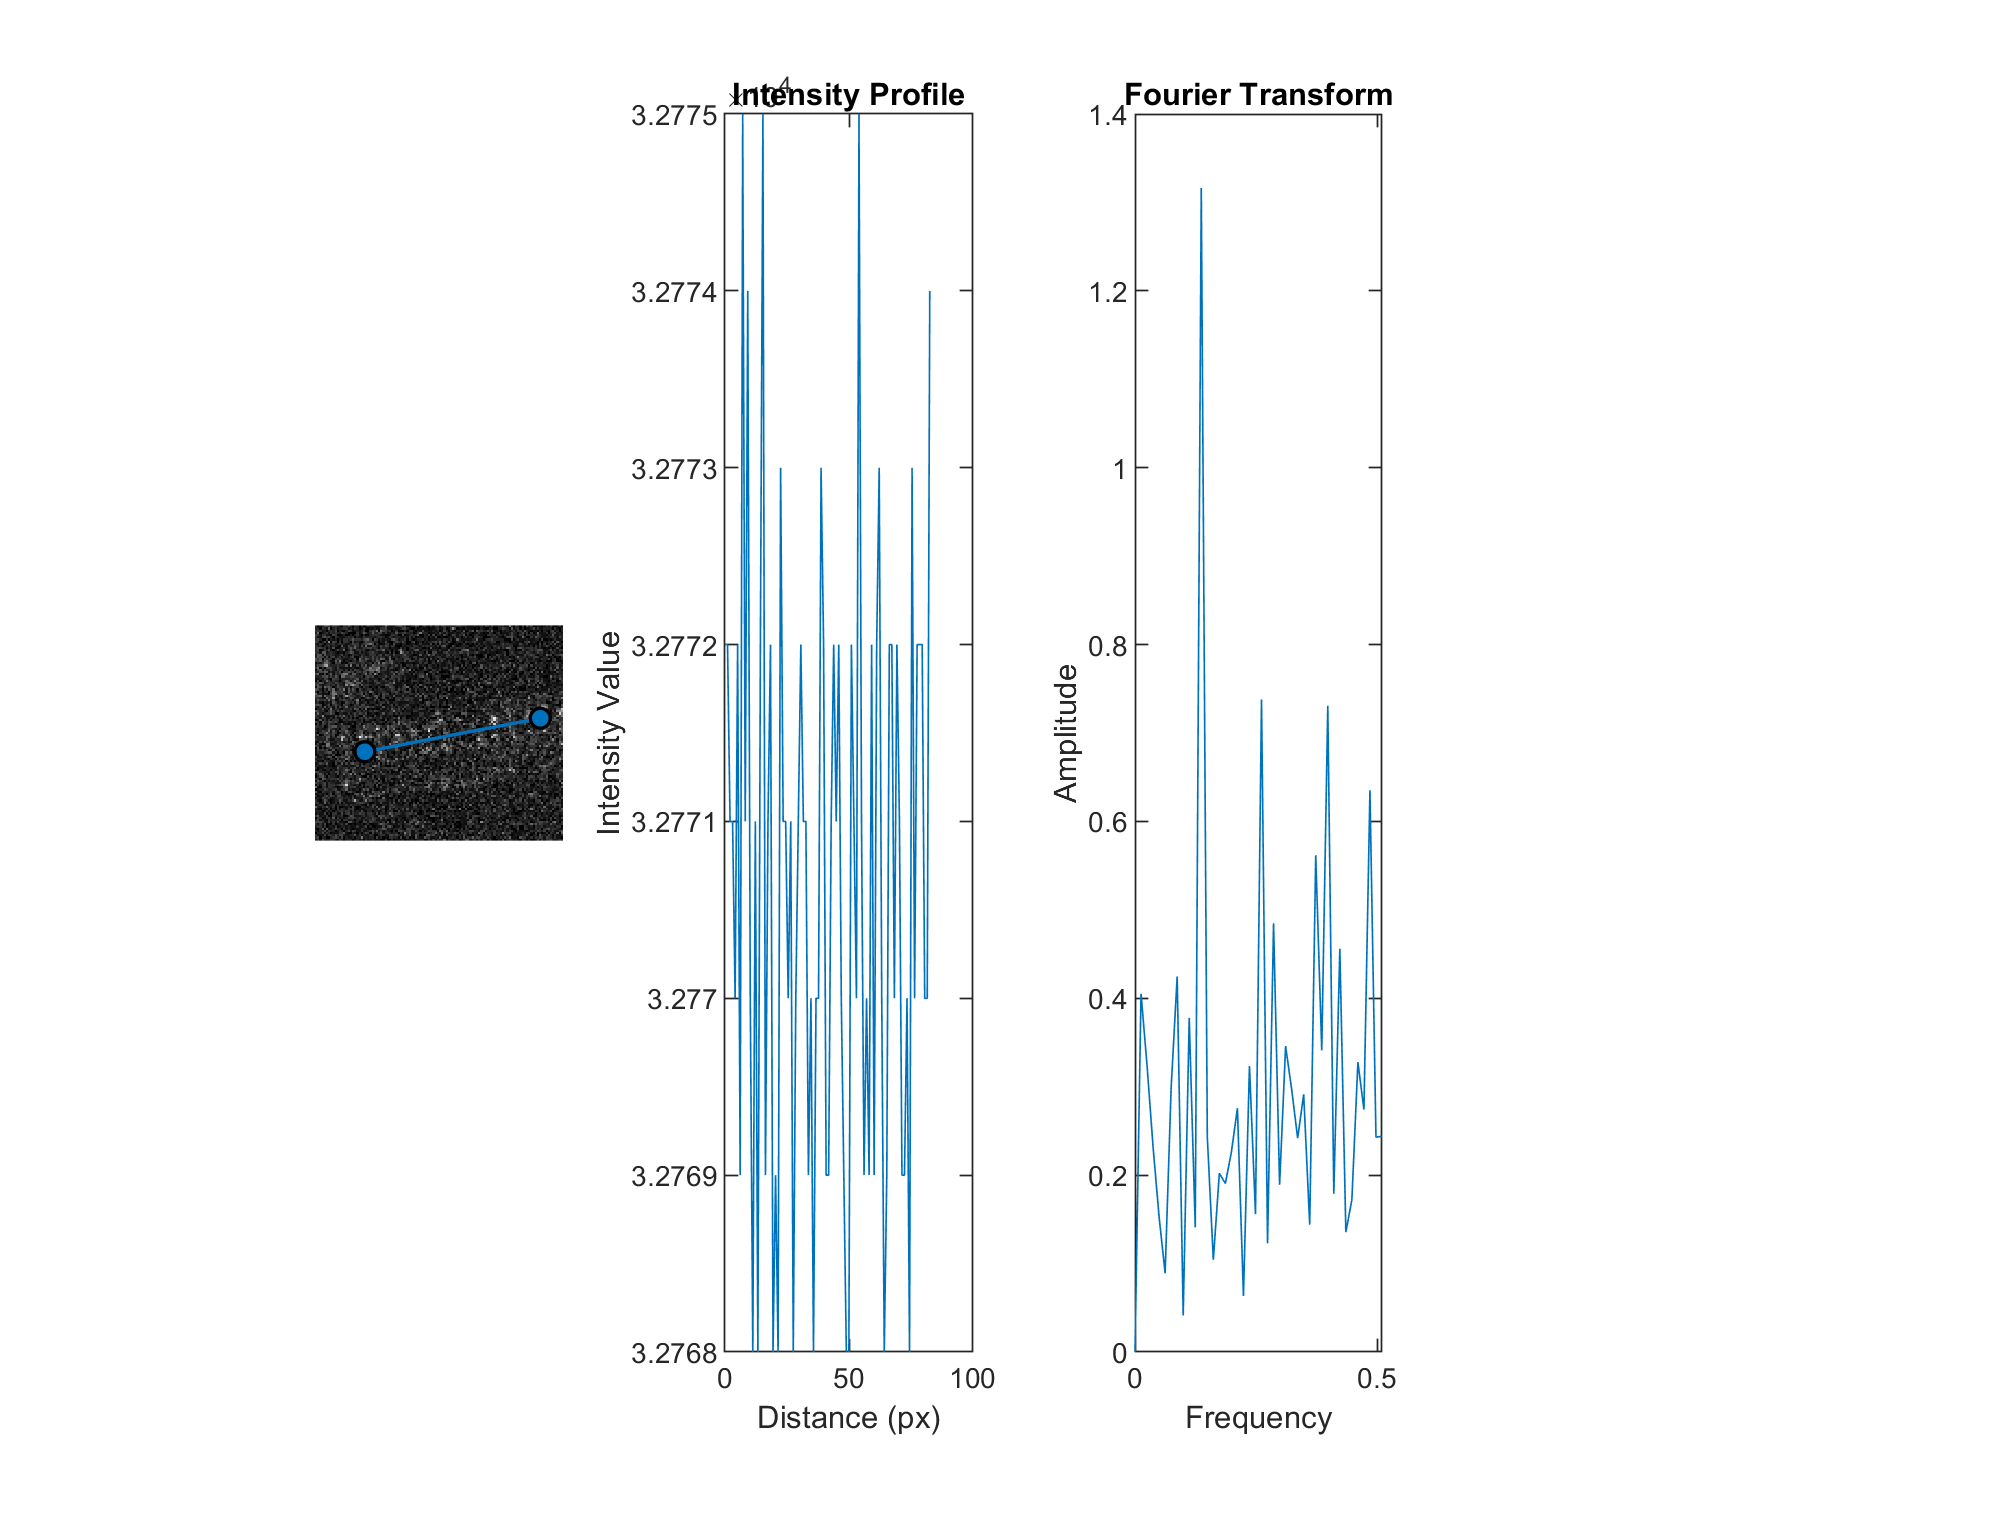

    {[0.1367]}    {[0.1298]}    {[0.1310]}    {[0.1325]}    {[0.0273]}    {[0.0217]}    {[0.0334]}



%% to open image
set(0,'DefaultFigureWindowStyle','docked')
% Step 1: Select multiple images
[filenames, path] = uigetfile('*.*', 'Select images', 'MultiSelect', 'on');

% Check if the selection was made
if iscell(filenames) || ischar(filenames)
    % Ensure filenames is a cell array for consistent processing
    if ischar(filenames)
        filenames = {filenames}; % Convert to cell array if only one file selected
    end

    % Initialize a figure for plotting
    hFig = figure;
    
    % Initialize variables to store the longest profile length and intensity data
    longestLength = 0;
    intensityProfiles = {};
    xValues = 1; % Placeholder for X values, will be adjusted for each profile
    
    % Process each selected image one by one
    for i = 1:length(filenames)
        % Read the current image
        img = imread(fullfile(path, filenames{i}));
        
        % Perform histogram equalization
        equalized_img = histeq(img);
        title(['Image: ', filenames{i}]);
        
        % Display the image in the left subplot
        subplot(1,4,1, 'Parent', hFig);
        %imshow(equalized_img);
        imshow(img, [min(img(:)), max(img(:))]);
        
        
        % Allow the user to draw a line ROI
        disp('Draw a ROI and press Enter');
        roi = drawline('LineWidth',1);
        wait(roi); % Wait for the user to finish drawing the ROI
        
        % Extract the ROI's position and intensity profile
        roiPosition = round(roi.Position);
        
        % Calculate the distance of the ROI in px
        distance = sqrt((roiPosition(2,1) - roiPosition(1,1))^2 + (roiPosition(2,2) - roiPosition(1,2))^2);
        fprintf('Distance: %.2f pixels\n', distance);
       
        % Get the coordinates of the line
        [x,y, intensityProfile] = improfile(img, roiPosition(:, 1), roiPosition(:, 2));
        
        % Calculate distances along the line
        points = sqrt((x - roiPosition(1,1)).^2 + (y - roiPosition(1,2)).^2);

        % Update the longestLength if the current profile is longer
        longestLength = max(longestLength, length(points));
        intensityProfiles{i} = points;
        %xValues = 1:(points); % Update X values based on current profile length
        
        % Plot the intensity profile in the right subplot
        subplot(1,4,2, 'Parent', hFig);
        plot(points, intensityProfile);
        title('Intensity Profile');
        xlabel('Distance (px)');
        ylabel('Intensity Value');
        
        %Calulate and plot the FFT frequency and amplitude
        intensity = intensityProfile(:,1);                  %intensity measurements
        x = points(:,1);                                 %distance(px)
        L = length(intensity);                              % number of samples
        Fs = mean(diff(x));                                 % Sampling Interval
        f = 1/Fs;                                           % Sampling Frequency
        Fn = Fs/2;                                          % Nyquist Frequency
        intensitymean = mean(intensity);                    % Mean Amplitude
        FTs = fft(intensity - intensitymean)/L;             % Fourier Transform
        Fv = linspace(0, 1, fix(L/2)+1)*Fn;                 % Frequency Vector
        Iv = 1:numel(Fv);                                   % Index Vector
        Amplitude = abs(FTs(Iv))*2;                         %get the absolute value of the amplitude
        subplot(1,4,3, 'Parent', hFig);
        plot(Fv, abs(FTs(Iv))*2);
        title('Fourier Transform');
        xlabel('Frequency');
        ylabel('Amplitude');

        % %tabulate (Freq, Amp)
        table_final = table(Fv', Amplitude)
        table_final.Properties.VariableNames = {'Frequency', 'Amplitude'}
        disp(table_final);
        
        % Initialize a cell array to store maxFreqValue for each image
        maxFreqValue = cell(length(filenames), 1);
        
        firstPeakXValue = cell(length(filenames), 1);

        % Find max amplitude and corresponding frequency
        [~, maxidx] = max(table_final.Amplitude);
        maxFreq = table_final(maxidx,:);
        maxFreqValue = maxFreq.Frequency;

         % Store maxFreqValue in the cell array
         maxFreqValuesCell{i} = maxFreqValue;
         disp(maxFreqValuesCell);
         
        % Find peaks in the signal
            % Find peaks in the 'Y' signal
                %[peaks, locations] = findpeaks(Amplitude);
                
                % Check if any peaks were found
                %if ~isempty(peaks)
                    % Get the x value at the first peak
                    %firstPeakXValue = Fv(locations(1));
                    
                    % Display the result
                    %fprintf('X value at the first peak: %f\n', firstPeakXValue);
                %else
                    %disp('No peaks found in the signal.');
                %end
         % Store firstPeakValue in the cell array
         %firstPeakXValues{i} = firstPeakXValue;
         %disp(firstPeakXValues);
         
        % Save the figure with a unique filename
        outputFilename = ['output_image_', num2str(i), '.svg'];
        saveas(hFig, outputFilename);

        % Pause to view before moving to the next image
        disp('Press any key to continue to the next image');
        pause;
    end
    
        %SummaryData.Frequency = [Fv']
        %if Fv < longestLength
            % Pad remaining entries with NaNs to avoid artificial zero influence
            %SummaryData(Fv+1:end,i+1) = NaN;
       % end
        %SummaryData.Amplitude = [abs(FTs(Iv))*2']
        %if abs(FTs(Iv))*2 < longestLength
            % Pad remaining entries with NaNs to avoid artificial zero influence
            %SummaryData((abs(FTs(Iv))*2)+1:end,i+1) = NaN;
            %end
        
     %tabulate intensity values
        intensityData = zeros(longestLength, length(filenames)+1);
        intensityData(:,1) = (1:longestLength)'; % First column for X values
        
        % Fill in the intensity data matrix with profiles, padding as needed
    for i = 1:length(intensityProfiles)
        profileLength = length(intensityProfiles{i});
        intensityData(1:profileLength,i+1) = intensityProfiles{i};
        if profileLength < longestLength
            % Pad remaining entries with NaNs to avoid artificial zero influence
            intensityData(profileLength+1:end,i+1) = NaN;
        end
        
      % After processing all images, create a table from the cell array
      % Display the maxFreqTable
       disp(maxFreqValuesCell);
       
       %Display the first peak values
       %disp(firstPeakXValues);
    
    end
    % Save the intensity plot information to a .mat file
    save('intensity_plot_xy_value.mat', 'intensityData');
    % Save the summary plot information to a .mat file
    save('max_freq_values', 'maxFreqValuesCell');
    %save('firstPeakXValues', 'firstPeakXValue')
    % Convert the tables to CSV files
    writematrix(intensityData, 'intensity_plot_xy_value.csv');
    writecell(maxFreqValuesCell, 'max_freq_values.csv')
    %writecell(firstPeakXValues, 'max_freq_values.csv')
else
    
    disp('No files selected.')
end


%transform max peakXvalues into acctual distance in nm

% Extract numeric values from the cell array
numericmaxPeakXValues = cellfun(@double, maxFreqValuesCell);

% Calculate the reciprocal for distance in pixels then convert to nanometers
Distance = (1 ./ numericmaxPeakXValues) .*25;

% Create a new table with the reciprocal values
TableDistance = table(Distance', 'VariableNames', {'Distance (nm)'});


% Display the table with reciprocal values
disp('Table with Reciprocal Values:');

Table with Reciprocal Values:


disp(TableDistance);

    Distance (nm)
    _____________

       1349.8    
       399.91    
       873.13    
       158.78    
       948.62    
       1148.9    
       158.28    
       137.58    
       163.71    
       156.87    
       818.53    
       1208.2    
       91.783    
       108.02    
       63.484    
       785.42    
       118.06    
        399.8    
       72.392    
       100.21    
       114.29    
       634.91    
       66.391    
         42.4    
       310.45    
       166.93    
       183.34    
       236.01    
       505.75    
       97.369    
       620.55    
        159.3    
       59.781    
       313.96    
       208.13    
       948.62    
       72.114    
       185.41    
       1047.3    
       458.35    
       202.18    
       141.45    
       59.353    
       307.36    
       105.41    
       155.26    
        159.3    
        143.1    
       197.77    
       445.71    




%Make final output table with frequency and distance
    % Convert the frequency cell array to a table
    %TablefirstPeakXValues = table(firstPeakXValues', 'VariableNames', {'Frequency'});
    TablemaxPeakXValues = table(maxFreqValuesCell','VariableNames',{'Frequency'});
    %Add distance to frequency table
    %TablefirstPeakXValues.Distance = Distance';
    TablemaxPeakXValues.Distance = Distance';
    

% Display the table with the new column
    disp('Table with Reciprocal Values:');

Table with Reciprocal Values:


    disp(TablemaxPeakXValues);

    Frequency     Distance
    __________    ________

    {[0.0185]}     1349.8 
    {[0.0625]}     399.91 
    {[0.0286]}     873.13 
    {[0.1575]}     158.78 
    {[0.0264]}     948.62 
    {[0.0218]}     1148.9 
    {[0.1580]}     158.28 
    {[0.1817]}     137.58 
    {[0.1527]}     163.71 
    {[0.1594]}     156.87 
    {[0.0305]}     818.53 
    {[0.0207]}     1208.2 
    {[0.2724]}     91.783 
    {[0.2314]}     108.02 
    {[0.3938]}     63.484 
    {[0.0318]}     785.42 
    {[0.2118]}     118.06 
    {[0.0625]}      399.8 
    {[0.3453]}     72.392 
    {[0.2495]}     100.21 
    {[0.2188]}     114.29 
    {[0.0394]}     634.91 
    {[0.3766]}     66.391 
    {[0.5896]}       42.4 
    {[0.0805]}     310.45 
    {[0.1498]}     166.93 
    {[0.1364]}     183.34 
    {[0.1059]}     236.01 
    {[0.0494]}     505.75 
    {[0.2568]}     97.369 
    {[0.0403]}     620.55 
    {[0.1569]}      159.3 
    {[0.4182]

    writetable(TablemaxPeakXValues, 'max_peak_values.csv')



% Create a histogram
    % Specify bin width
    binWidth = 50;

    % Calculate the number of bins based on the bin width
    numBins = ceil((max(Distance) - min(Distance)) / binWidth);
    disp(max(Distance))

   1.3498e+03



    disp(min(Distance))

   42.3999



    disp(numBins)

    27



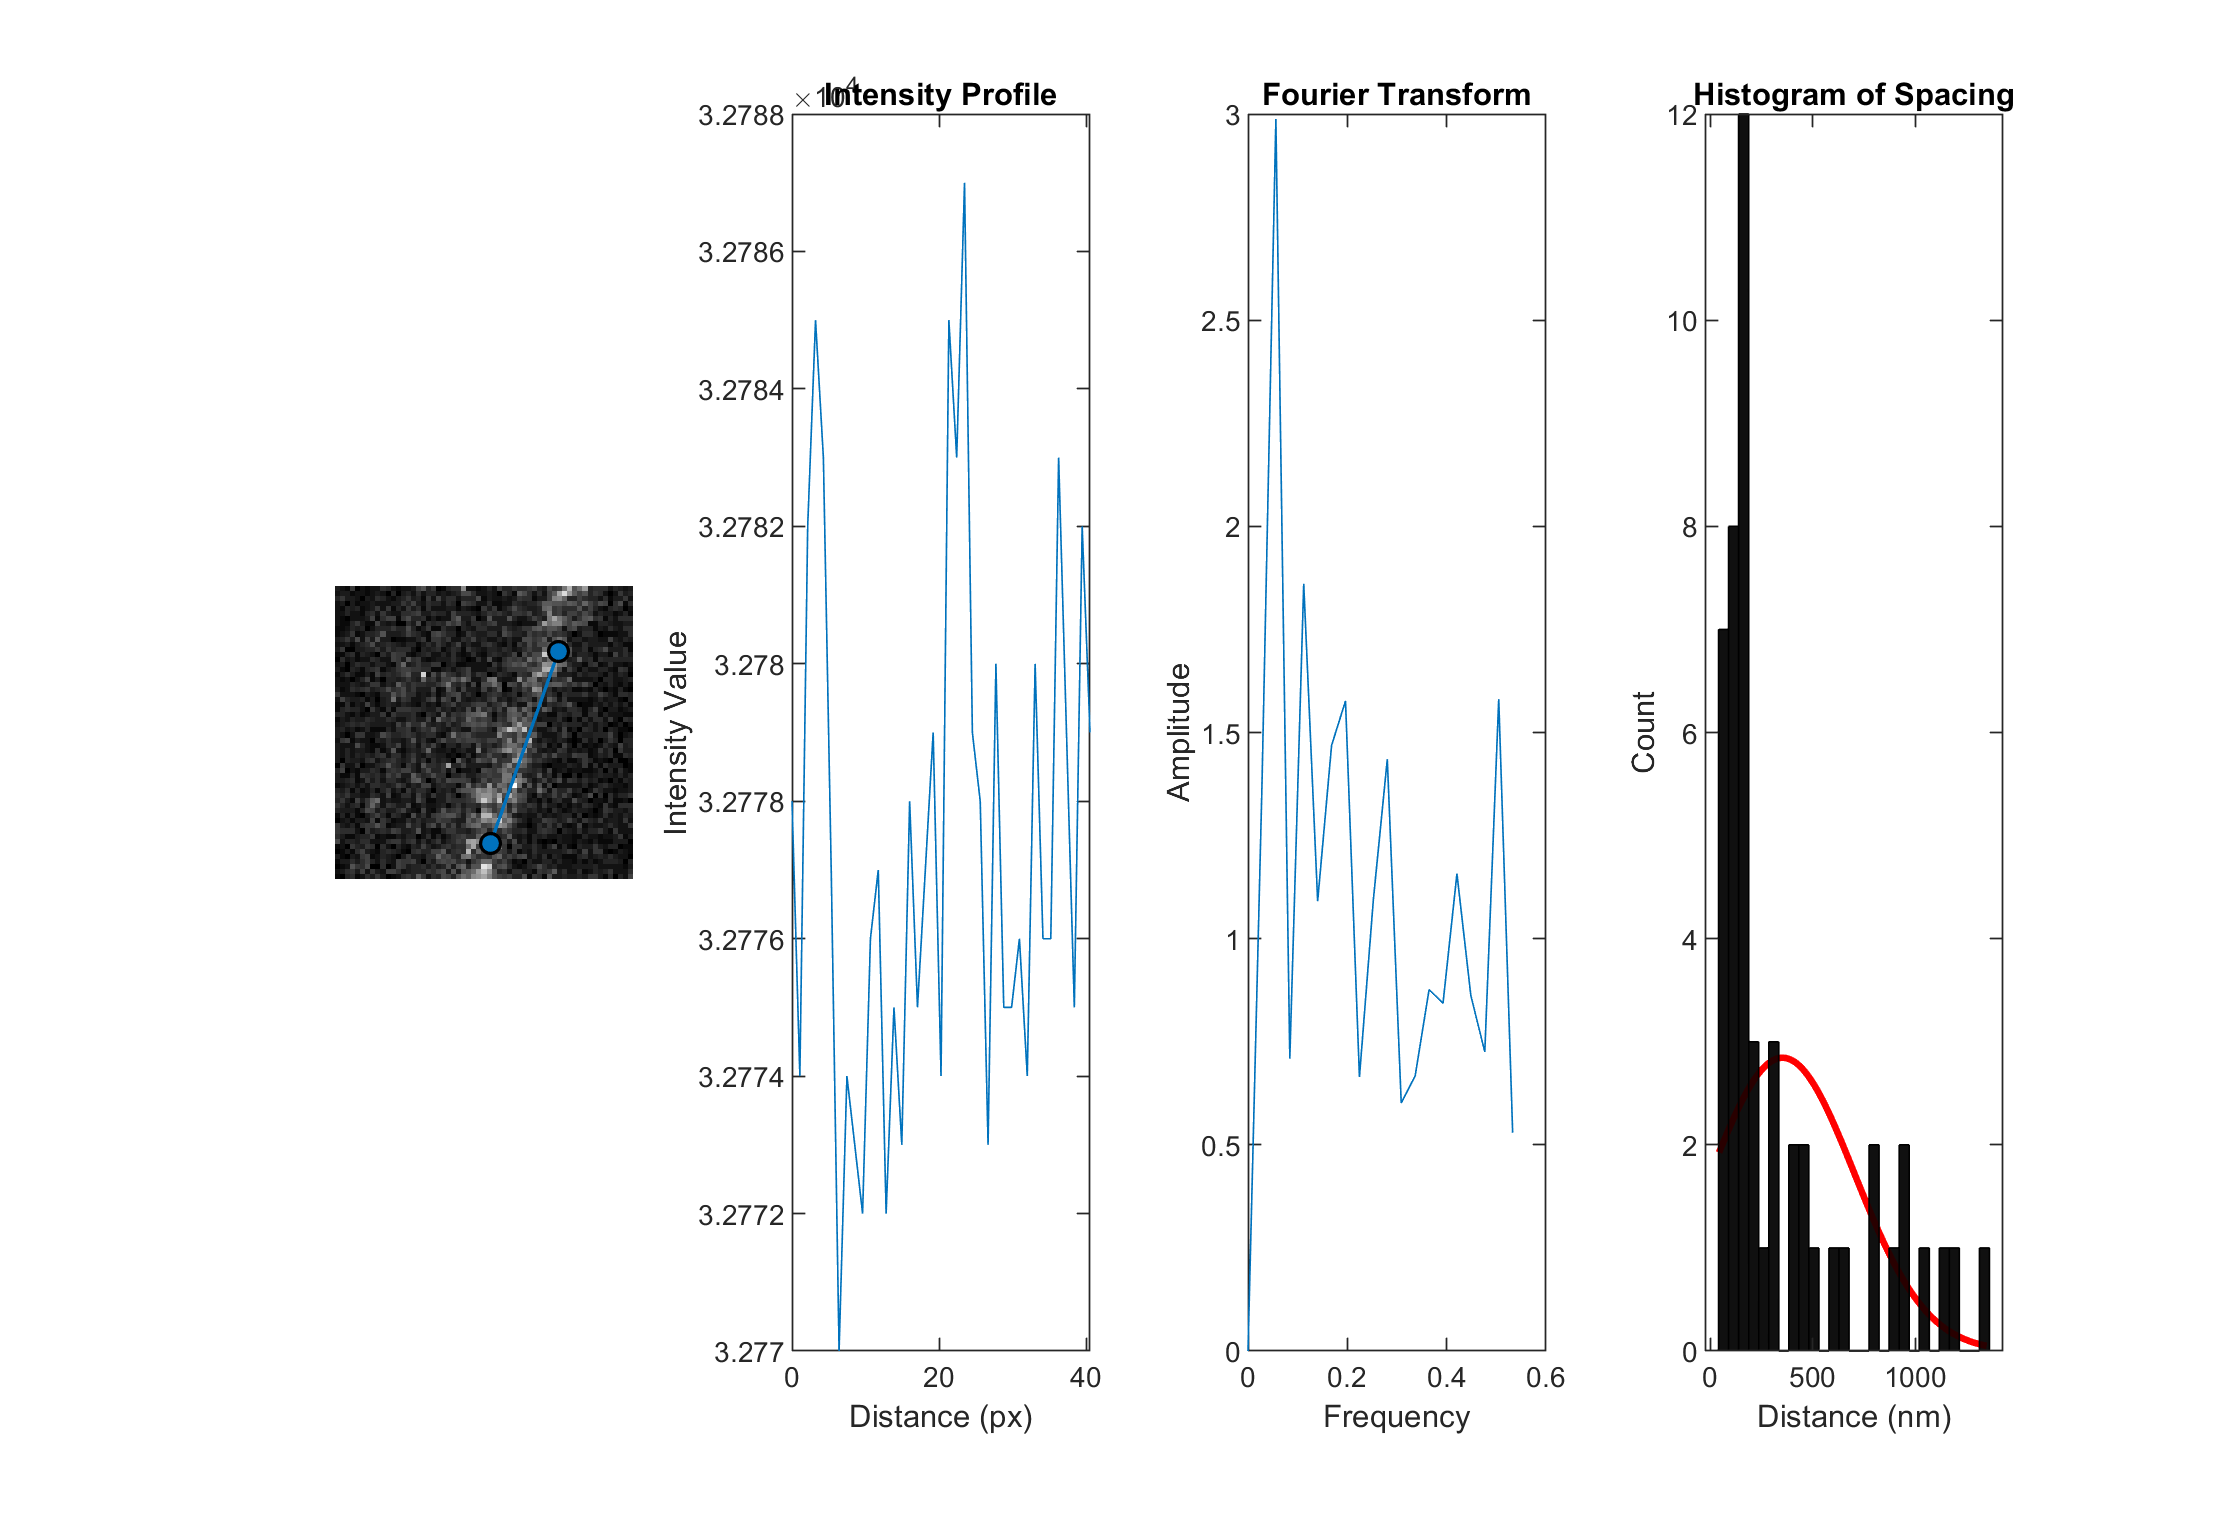

    
    % Create the fourth subplot
    subplot4 = subplot(1, 4, 4);

    % Create a histogram with specified bin width
    histogram(Distance, 'BinWidth', binWidth, 'FaceColor', 'black', 'EdgeColor', 'black', 'NumBins', numBins);
    
    % Add labels and title
    xlabel('Distance (nm)');
    ylabel('Count');
    title('Histogram of Spacing');


% Assuming Distance is a row vector
Distance = Distance';  % Transpose to convert to a column vector    

%cla(subplot4)

% Fit a Gaussian distribution
pd = fitdist(Distance, 'Normal');

% Plot the Gaussian fit over the histogram
hold on;
x = linspace(min(Distance), max(Distance), 1000);
y = pdf(pd, x);
plot(x, y * numel(Distance) * binWidth, 'r', 'LineWidth', 2);

% Display mean and standard deviation
disp(['Mean: ', num2str(pd.mu)]);

Mean: 352.1941


disp(['Standard Deviation: ', num2str(pd.sigma)]);

Standard Deviation: 350.6169


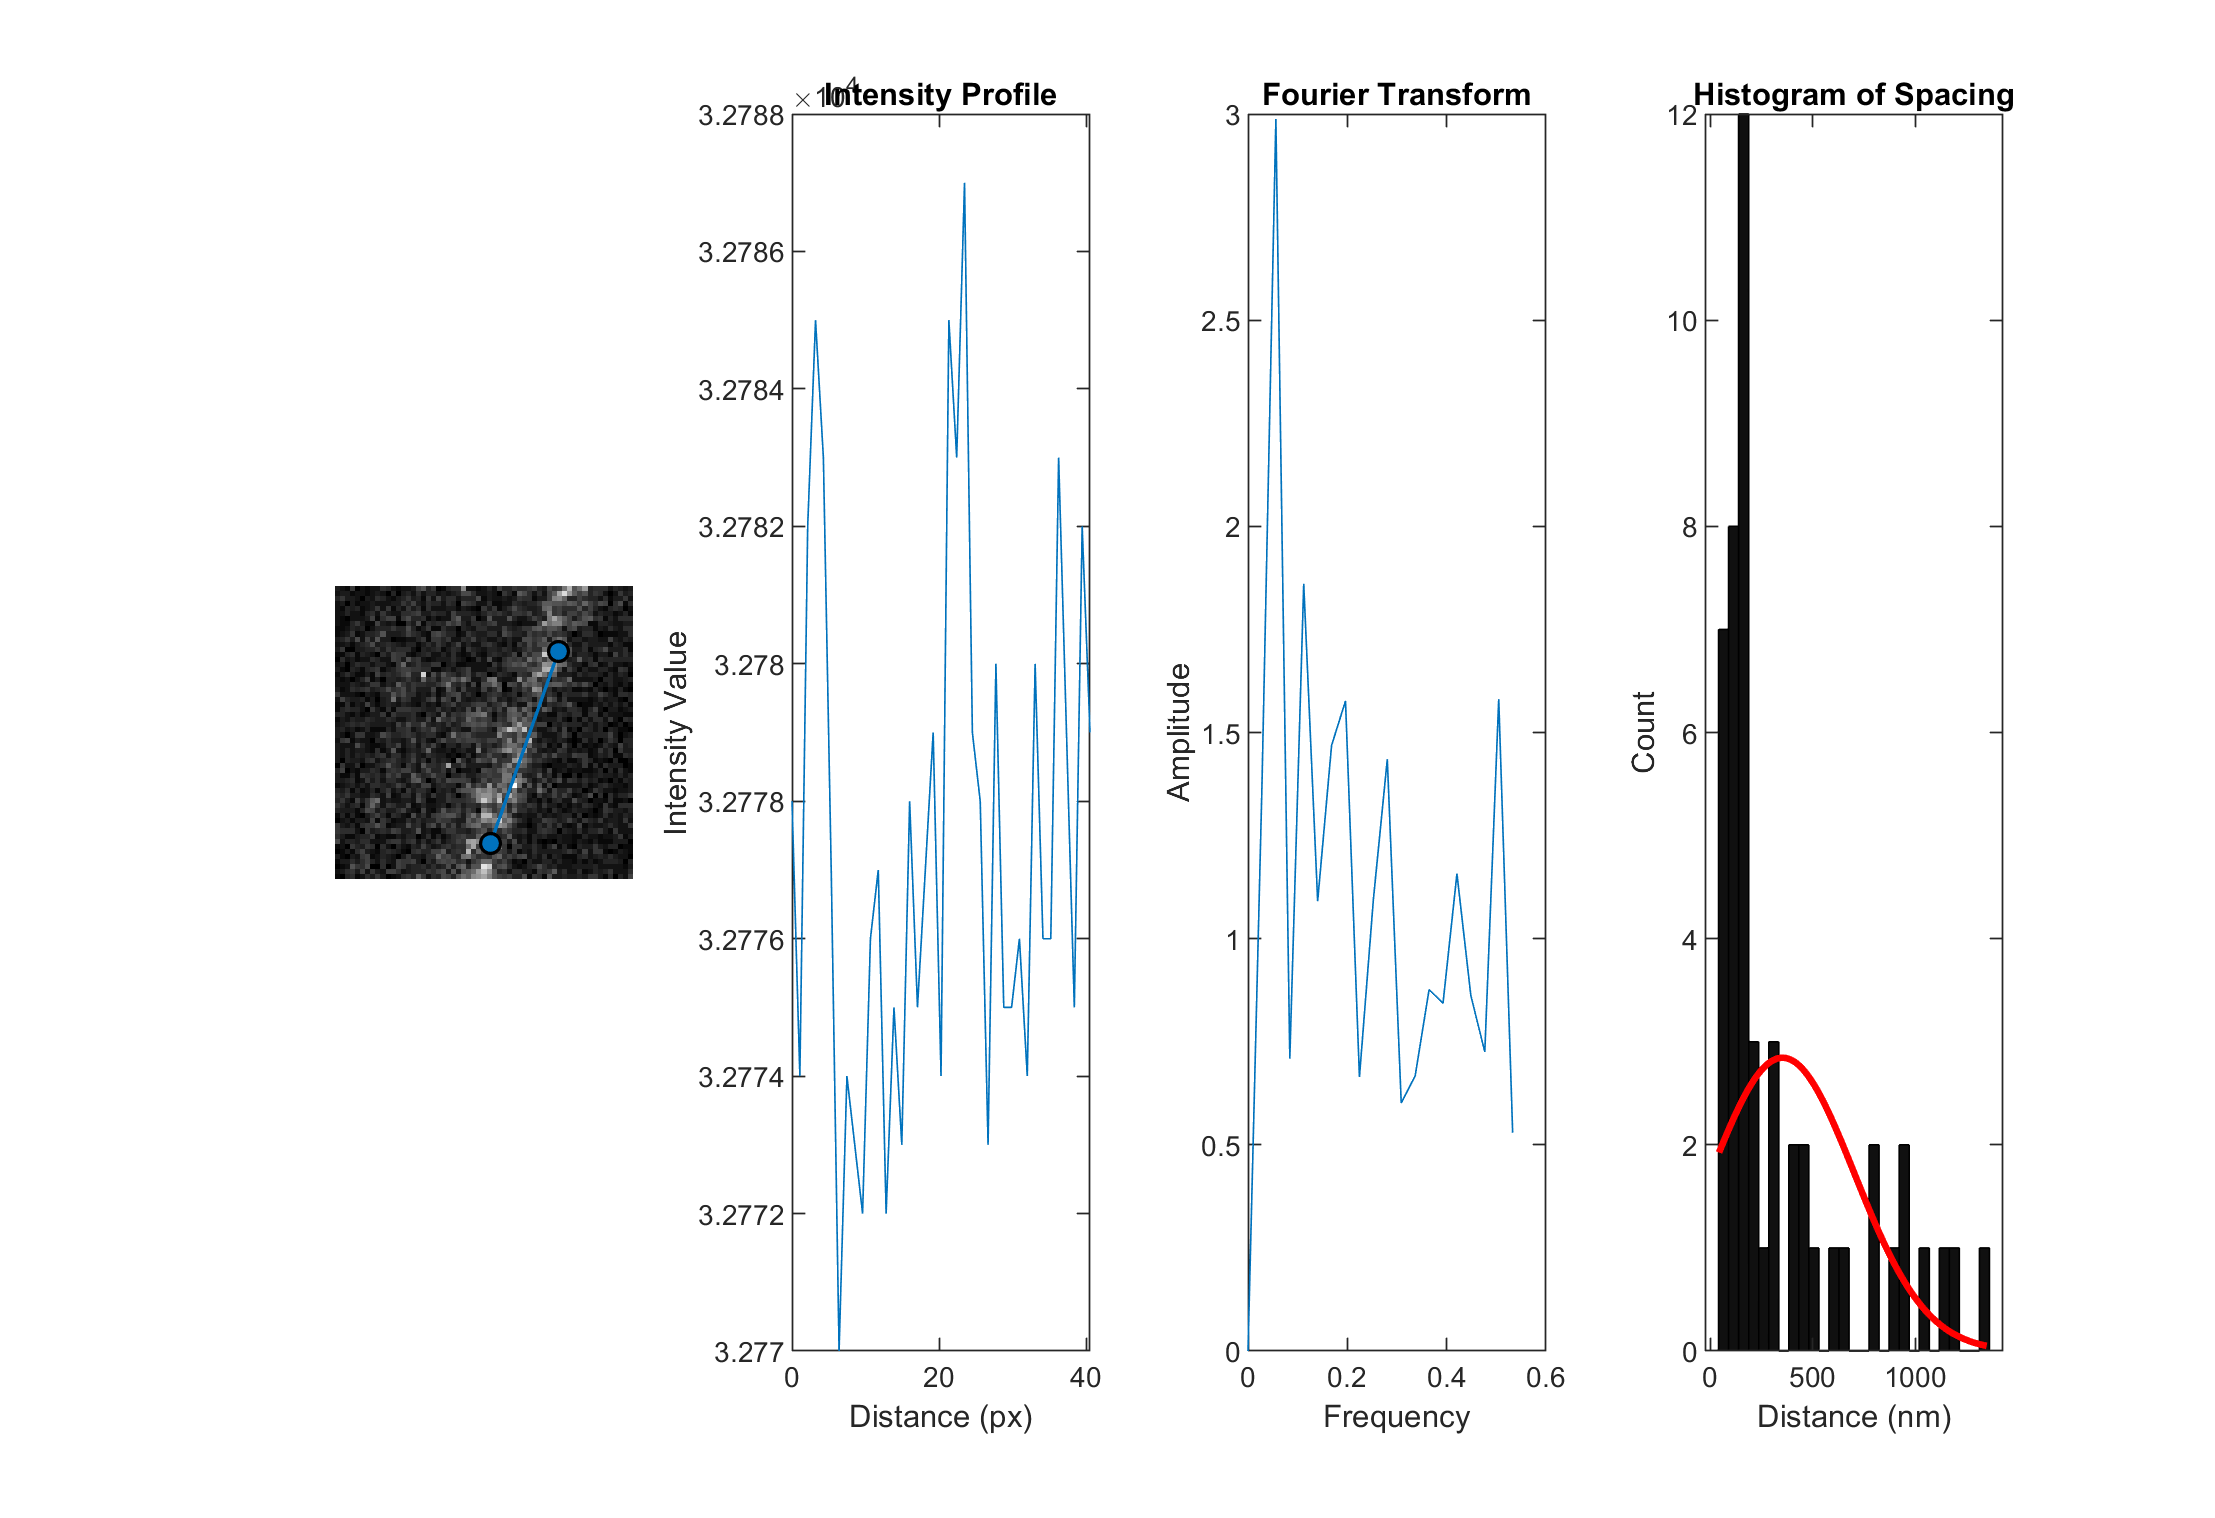


%export final figure
saveas(hFig,'final_figure.svg')